
a=[0;2;3;5;8;11;12;15];
b=[50;56;60;72;85;100;110;125];

A_lin=[ones(8,1) a];
A_para=[ones(8,1) a a.*a];

lincoeff=lsqr(A_lin,b);

lsqr converged at iteration 2 to a solution with relative residual 0.025.


paracoeff=lsqr(A_para,b);

lsqr converged at iteration 3 to a solution with relative residual 0.017.


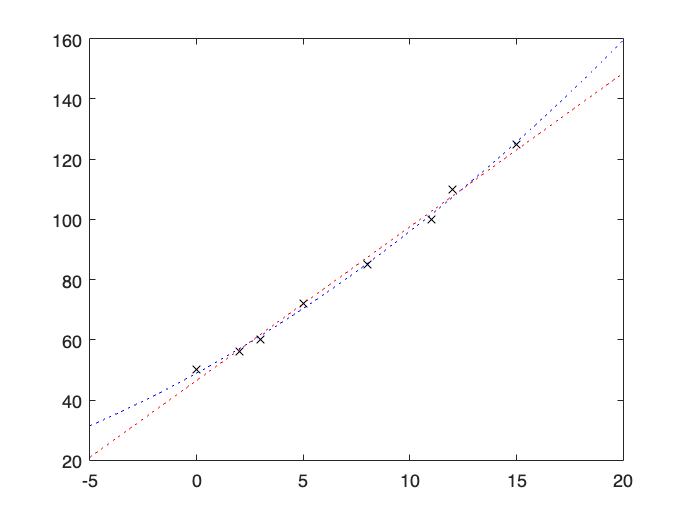


x=linspace(-5,20,1000);
lin=lincoeff(1,1)+lincoeff(2,1).*x;
para=paracoeff(1,1)+paracoeff(2,1).*x+paracoeff(3,1).*(x.^2);

plot(a,b,'kx');hold on;
plot(x,lin,':r');plot(x,para,':b');


condAlin=cond(A_lin,2)

condAlin = 14.9330

condApara=cond(A_para,2)

condApara = 252.7341